# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*-------------------------------------------------------------------------------------------------------------------------------*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

*--------------------------------------------------------------------------------------------------------------------------------*

###  **Neurophysiological Mechanisms of ERPs** 

Compared to oscillations, there is less empirical and theoretical work on the neurophysiological mechanisms that produce event-related potentials (ERPs)—that is, why there are positive and negative polarity peaks at somewhat regularly spaced intervals following experiment events.   

- *Additive *This model proposes that the ERP reflects a signal that is elicited by an external stimulus such as a picture or a sound or by an internal event such as the initiation of a manual response and is added to ongoing background oscillations.

- *Phase reset *This model proposes that ERPs result at least partially from a sudden alignment of the phases of ongoing oscillations (Makeig et al. 2002).

-----------------------------------------------------------------------------------------------------------

###  **Neurobiological Mechanisms of Oscillations**

The neurobiological mechanisms that produce oscillations are fairly well understood (Buzsaki, Anastassiou, and Koch 2012; Wang 2010), although uncertainties remain in the extent *to which different factors contribute to the signal recorded by EEG*, in part due to the complexity of the models and the difference in spatial scale between individual neurons and scalp EEG (Coombes 2010; Deco et al. 2008; Whittingstall and Logothetis 2009).

- Interactions between inhibitory (GABAergic) interneurons and excitatory pyramidal cells 

*-----------------------------------------------------------------------------------------------------------*

### **Advantages and Limitations of Event-Related Potentials**  

#### **1. Adv:**

- ERPs are simple and fast to compute and require few analysis assumptions or parameters.

- ERPs generally involve very little data processing and gentle or no temporal filters, the estimate of electrical activity at each millisecond is very precise.  (*Note: that when low-pass filters or high-pass filters are applied to ERPs, their temporal precision decreases.*)

- There is an extensive and decades-long literature of ERP findings in which to contextualize and interpret your results.

- They provide a quick and useful data quality check of single subject data. (*Note: visual evoked response over posterior occipital and parietal electrodes, followed by a P3-type component over central and parietal electrodes.*)

#### 2. Limit:

- ERPs reveal relatively little of the information present in EEG data, as will become clear throughout this book. In other words there are many kinds of dynamics in EEG data that do not have a representation in the ERP.

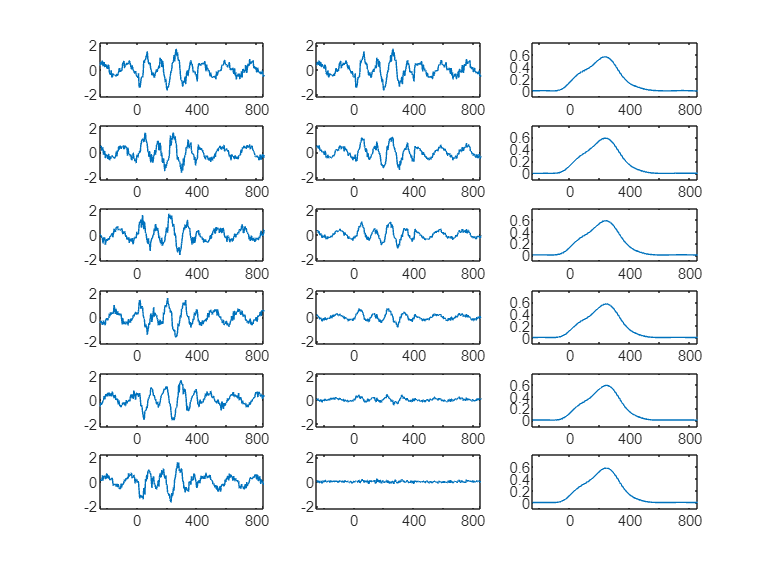

% Single trials were simulated by creating a 6-Hz sine wave and adding a 10-Hz stimulus response and some noise. 

load sampleEEGdata.mat
nTrials = 6; % modifiable
figure
data = zeros(nTrials,EEG.pnts);

% wavelet
wavetime   = -1:1/EEG.srate:1;
n_conv     = length(wavetime)+EEG.pnts-1;
waveletfft = fft(exp(2*1i*pi*10.*wavetime) .* exp(-wavetime.^2./(2*(5/(2*pi*10))^2))/10,n_conv);
data10hz   = zeros(nTrials,EEG.pnts);

for triali=1:nTrials
    
    % create single trial "ERP"
    data(triali,:) = .5*sin(2*pi*6.*EEG.times/1000 + 2*pi*triali/nTrials-pi) + randn(1,EEG.pnts)/6;
    % add non-phase-locked stimulus potential (note distributed phases in sine wave)
    data(triali,260:360) = data(triali,260:360) + sin(2*pi*10.*EEG.times(260:360)/1000 + 2*pi*triali/nTrials-pi) + randn(1,101)/5;
    
    
    % plot data from this trial
    subplot(nTrials,3,(triali-1)*3+1)
    plot(EEG.times,data(triali,:))
    set(gca,'xlim',[-250 850],'ylim',[-2.2 2.2])
    
    % plot ERP from trial 1 to current
    subplot(nTrials,3,(triali-1)*3+2)
    plot(EEG.times,mean(data(1:triali,:),1))
    set(gca,'xlim',[-250 850],'ylim',[-2.2 2.2])
    
    % convolve with 10 Hz wavelet (more on convolution in a few chapters...)
    convolution_result_fft = ifft(waveletfft.*fft(data(triali,:),n_conv)) * sqrt(5/(2*pi*10));
    convolution_result_fft = convolution_result_fft(floor(length(wavetime)/2)+1:end-floor(length(wavetime)/2));
    data10hz(triali,:) = abs(convolution_result_fft).^2;
    
    % plot 10 Hz power
    subplot(nTrials,3,(triali-1)*3+3)
    plot(EEG.times,mean(data10hz(1:triali,:),1))
    set(gca,'xlim',[-250 850],'ylim',[-.1 .8])
end

- They provide limited opportunities for linking results to physiological mechanisms.

-----------------------------------------------------------------------------------------------------------

### **Advantages and Limitations of Time-Frequency-Based Approaches**

#### **1. Adv:**

- Many results from time-frequency based analyses can be interpreted in terms of neurophysiological mechanisms of neural oscillations.

- Oscillations are arguably the most promising bridge that links findings from multiple disciplines within neuroscience and across multiple species.

- If you accept that EEG data capture a dynamic and multidimensional space of brain processing, then ERPs reveal a fraction of that space, and time-frequency-based analyses reveal more (although not all) of that space.

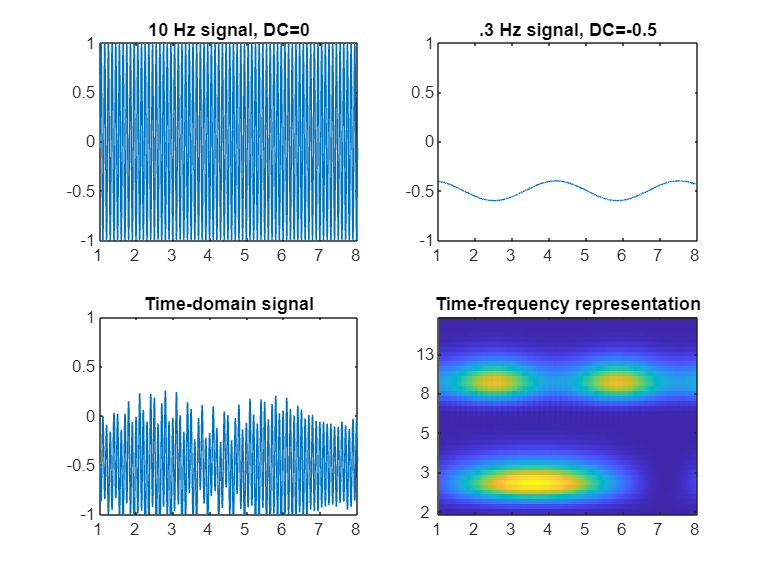

srate=1000;
time=(0:1/srate:10);

DCoffset=-.5;

% create multi-frequency signal
a = sin(2*pi*10.*time);             % part 1 of signal (high frequency)
b = .1*sin(2*pi*.3*time)+DCoffset;  % part 2 of signal (low frequency)

data = a.*b; % combined signal
data = data + (2*sin(2*pi*3*time) .* sin(2*pi*.07*time)*.1+DCoffset);

% morlet wavelet convolution (more on this in later chapters)
num_frex = 40;
min_freq =  2;
max_freq = 20;

Ldata  = length(data);
Ltapr  = length(data);
Lconv1 = Ldata+Ltapr-1;
Lconv  = pow2(nextpow2(Lconv1));

frex=logspace(log10(min_freq),log10(max_freq),num_frex);

% initialize
tf=zeros(num_frex,length(data));
datspctra = fft(data,Lconv);

s=4./(2*pi.*frex);
t=-((length(data)-1)/2)/srate:1/srate:((length(data)-2)/2)/srate+1/srate;

for fi=1:length(frex)
    
    wavelet=exp(2*1i*pi*frex(fi).*t).*exp(-t.^2./(2*s(fi)^2));
    
    m = ifft(datspctra.*fft(wavelet,Lconv),Lconv);
    m = m(1:Lconv1);
    m = m(floor((Ltapr-1)/2):end-1-ceil((Ltapr-1)/2));
    
    tf(fi,:) = abs(m).^2;
end


figure

subplot(221)
plot(a)
set(gca,'xlim',[1 8]*1000,'ylim',[-1 1],'xtick',0:1000:10000,'xticklabel',0:10);
title('10 Hz signal, DC=0')

subplot(222)
plot(b)
set(gca,'xlim',[1 8]*1000,'ylim',[-1 1],'xtick',0:1000:10000,'xticklabel',0:10);
title([ '.3 Hz signal, DC=' num2str(DCoffset) ])

subplot(223)
plot(data)
set(gca,'xlim',[1 8]*1000,'ylim',[-1 1],'xtick',0:1000:10000,'xticklabel',0:10);
title('Time-domain signal')

subplot(224)
imagesc(1:length(data),[],tf);
set(gca,'xlim',[1 8]*1000,'ydir','normal','ytick',1:8:num_frex,'yticklabel',round(frex(1:8:end)),'xtick',0:1000:10000,'xticklabel',0:10)
title('Time-frequency representation')

#### 2. Limitation

- Decrease of temporal precision resulting from time-frequency decomposition. (*Note: lower frequencies generally suffer from more loss of temporal precision*)

-  large number of analyses that can be applied to EEG data, and the seeming complexity of those analyses, can be intimidating. *Note: Guys, at this point of your scientific journey, please trust packages for time-frequency analysis, and dont write down codes from scratch, especially if your code is not going to be review by an expert, cause definitely you will miss a point :)*

### **Topographical Localization versus Brain Localization**  

*Topographical localization* refers to identifying the electrodes that show the maximum effect under investigation. For example the error-related negativity can be measured from many electrodes, but it can be topographically localized to electrode Cz or FCz. Topographical localization does not necessarily mean that the activity was generated by neural populations directly underneath that electrode, although this may be the case, for example, with radial EEG dipoles after the surface Laplacian has been applied.

*Brain localization* refers to identifying the locations in the brain that generated the activity measured from the scalp. Brain localization is more difficult to determine and involves greater uncertainty than topographical localization, in part because brain localization relies on several assumptions about brain shape, electrical conductivity, and so on, and in part because the inverse problem has many possible solutions that are equally likely (that is, a large number of plausible brain states could produce the same topographical distribution of activity).

-------------------------------------------------------------------------------------------------------------

#### **Exercise 3:**

#### **Are Electrical Fields Causally Involved in Cognition?** 

*Prepare your answer after reading this paper*